Simulate bacterial growth using the Euler method.

First, define the model parameters

k = 1/20; %in 1/min

To define the initial condition, let's learn something about vectors in Matlab

a = [1,4,2,5,3]

a =      1     4     2     5     3


Matlab indices start at 1, not 0 like most other programming languages. If I want to get the second element of the vector, I do the following:

a(2)

ans = 4

If I want to change the content of the 3rd element, I do

a(3)=10

a =      1     4    10     5     3


If I want to add a 6th element to it, I do

a(6)=20

a =      1     4    10     5     3    20


Now we can define the vector for the number of cells. Each element will correspond to a time point in the simulation. I start with the initial condition:

N(1)=1; %start with 1 cell

Next, define the simulation parameters

dt=0.1; %in minutes
Nsteps=1000;

We're ready to do the Euler integration. So that we don't need to type everything up step by step, we're going to use a for-loop.

for i=1:10 %counter i that will move between 1 and 10
i
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

Let's define a time vector for our x-axis.

Time(1)=0;

We'll use a for loop to solve the equation. Our index is going to move through the time steps. Since we've already given it what the first step is as our initial condition, we'll start our index with step 2.

for i=2:Nsteps
    N(i)=N(i-1)+(k*dt*N(i-1));
    Time(i)=Time(i-1)+dt;
end

Plot the results.

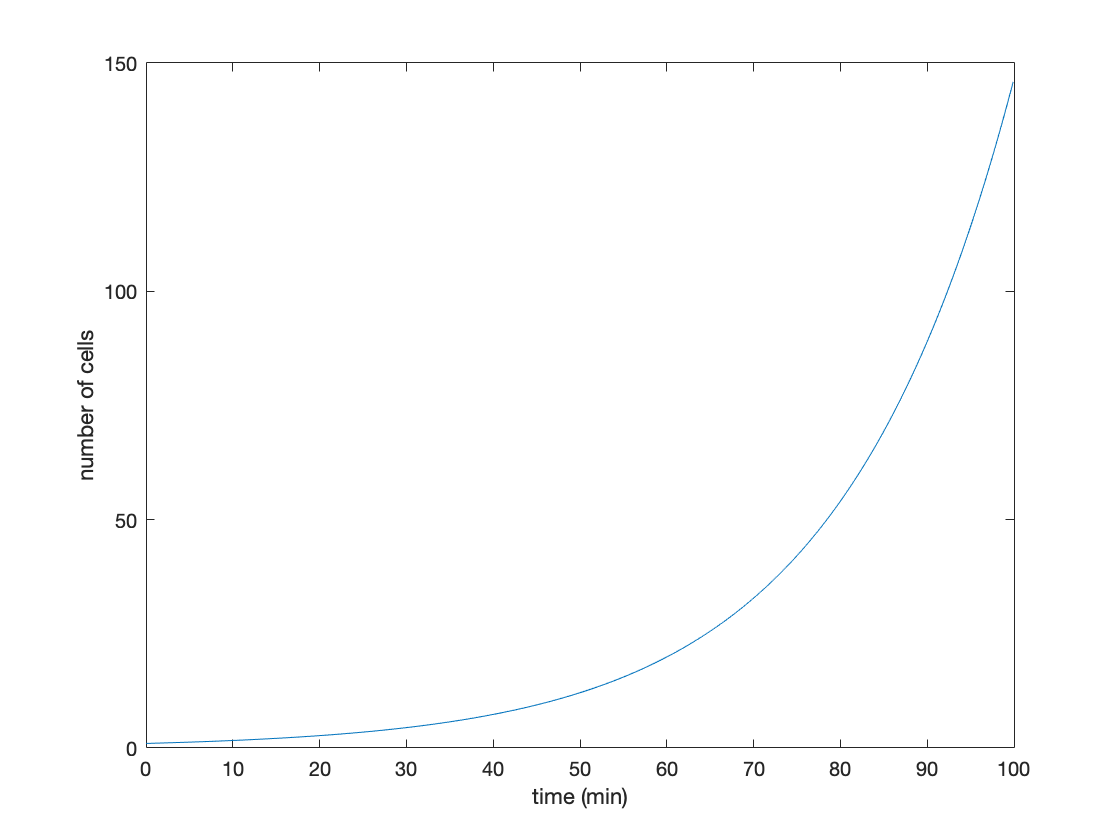

plot(Time, N)
xlabel('time (min)')
ylabel('number of cells')

This looks like exponential growth. Let's verify that by plotting using a log scale on y.

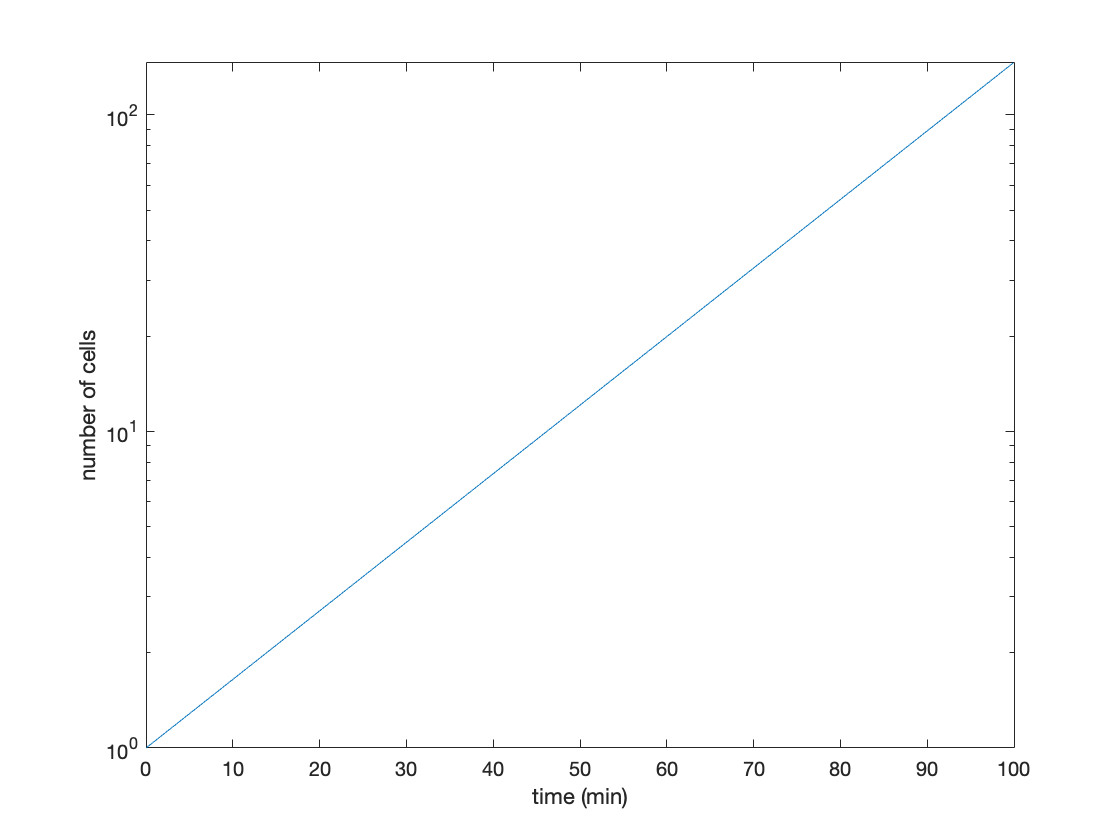

semilogy(Time, N)
xlabel('time (min)')
ylabel('number of cells')

How long would it take for *E. coli* doubling every 30 mins to cover the whole surface of the Earth? Diameter of Earth is 12,756km.

Rearth=12756/2

Rearth = 6378

Asurface = 4*3.14*(Rearth^2)

Asurface = 5.1093e+08

Aecoli = 6um^3=6((10)^-6m)^3=few(10)^-18

Asurface/(10^-18)

ans = 5.1093e+26

# doublings: 2^N = few*10^26. Solve for N.